## **Liperior 16000mAh 6S 12C 22.2V Lipo Battery**

- Cell Mass - 1.847kg/6 = 0.30783kg

- Cell capacity - 16Ah/6 = 2.6666

- Cell count - 6s

- Cell Voltage - 3.7v

- Cell Geometry - 0.0312m x 0.01242m x 0.0103m  (lHeight x length x thickness) (m)

- Cell Energy - 355.20/6 = 59.2 wh

- Estimated Heat Capacity each cell - 166.6667*0.30783 = 51.305 J/K

## Load Battery Model 

load ("FM_Batteries10.mat")
load("matlab.mat")

## Read the Flight Data from Forward Battery

FlightData = ardupilotreader("C:\Users\PC\OneDrive\Documents\MATLAB\eVTOL_Simulator\ForwardBatteryModel\00000007(foward_flight).BIN");
SID_Data = readMessages(FlightData,"MessageNames","BAT");

## Index Data

Voltage = SID_Data.MsgData{2,1}.Volt(1:end);
Current = SID_Data.MsgData{2,1}.Curr(1:end);
VoltR = SID_Data.MsgData{2,1}.VoltR(1:end);
CurrentTotal = SID_Data.MsgData{2,1}.CurrTot(1:end);
EnergyTotal = SID_Data.MsgData{2,1}.EnrgTot(1:end);
Temperature = SID_Data.MsgData{2,1}.Temp(1:end);
Resistance = SID_Data.MsgData{2,1}.Res(1:end);
TimeStamp = duration(SID_Data.MsgData{2,1}.TimeUS(1:end)) - SID_Data.MsgData{2,1}.TimeUS(1);
Time = seconds(TimeStamp);
Voltage_ts = timeseries(Voltage, Time); Current_ts = timeseries(Current, Time);
VoltR_ts = timeseries(VoltR, Time); CurrentTotal_ts = timeseries(CurrentTotal, Time);
EnergyTotal_ts = timeseries(EnergyTotal, Time); Resistance_ts = timeseries(Resistance, Time);

## Create and Index Battery Data

% The code following this point wraps all of the data into a dataset file
% to be loaded into the signal editor
Battery_Data = Simulink.SimulationData.Dataset;
Battery_Data = Battery_Data.addElement(Voltage_ts, "Voltage");
Battery_Data = Battery_Data.addElement(Current_ts, "Current");
Battery_Data = Battery_Data.addElement(VoltR_ts, "VoltR");
Battery_Data = Battery_Data.addElement(CurrentTotal_ts, "Total Current");
Battery_Data = Battery_Data.addElement(EnergyTotal_ts, "Total Energy");
Battery_Data = Battery_Data.addElement(Resistance_ts, "Resistance");

## Plotting Voltage vs. Time with Simulation and Flight

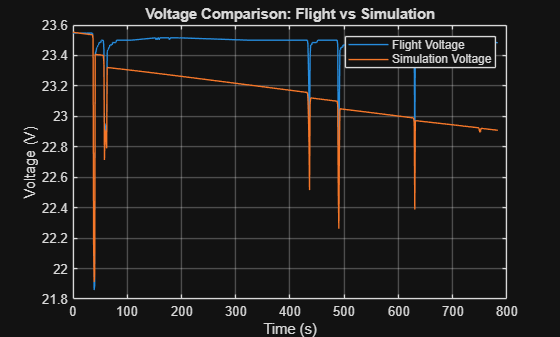

plot(FlightV.Time,FlightV.Data);
hold on
plot(FlightV.Time,SimulationV.Data);
hold off
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Voltage Comparison: Flight vs Simulation');
legend('Flight Voltage', 'Simulation Voltage');
grid on;